# Trabajo Grupal 3. Simulación de colas $$M/M/K/K$$, Erlang-B.

Autores: Joan Camilo Peña, Jeisson Alejandro Hernandéz, Jhon Alejandro Morales.

Mayo 25 de 2024.

## Introducción

Este es un modelo de colas exponencial con un número limitado de servidores y con pérdidas. Consideramos otra vez que el número de fuentes es infinito y, por lo tanto, tenemos una tasa de llegadas constante $ $\lambda$$ y una tasa de servicio $$\mu$$ en cada servidor. Las llegadas llegan aleatoriamente. Cada estado representa el número de unidades en la cola de espera. En este caso, el sistema sólo tiene c servidores con un número máximo de unidades en el sistema de c elementos. Por lo tanto, no hay cola de espera, y las unidades que se encuentren los servidores ocupados se perderán sin tener la posibilidad de ser almacenadas (Rocafiguera & Barberán, 2019).

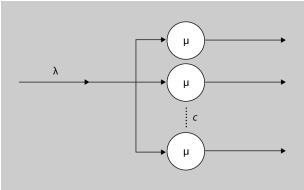

*Figura Modelo de* cola $$$M/M/c/c
$ Erlang B (Rocafiguera & Barberán, 2019).

## Primera Actividad

Construyan el modelo matemático de la cola asignada a su grupo. El modelo debe incluir: diagrama de transición de estados, ecuaciones de estado estacionario y el procedimiento matemático que permita calcular la medida de desempeño de interés (propabilidad de bloqueo: Pk para$$M/M/K/K$$).

### Construcción del modelo matemático.

Se establece el diagrama de transición de estados.

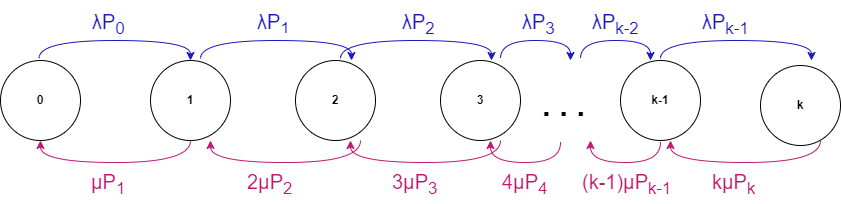

*Figura D*iagrama de transición de estados para cola $$M/M/K/K$$ 

      Se obtienen las ecuaciones de estado estacionario.


$$
 \lambda P_0 = \mu P_1  \text{ (Ecuación 1)}



$$



$$\lambda P_1 + \mu P_1 = \lambda P_0 + 2\mu P_2  \text{    (Ecuación 2)}



$$



$$\lambda P_2 +2\mu P_2 =\lambda P_1 + 3\mu P_3  \text{ (Ecuación 3)}



$$



$$\vdots \\



$$



$$\lambda P_{k-1} +(k-1)\mu P_{k-1} =\lambda P_{k-2} + k\mu P_k  \text{ (Ecuación 4)}



$$



$$k\mu P_{k} =\lambda P_{k-1}  \text{ (Ecuación 5)}



$$



$$P_1=\frac{\lambda}{\mu} P_0   \text{ (De Ecuación 1)}



$$



$$P_2=\frac{\lambda}{2\mu} P_1 =\frac{\lambda^2}{2\mu^2} P_0  \text{ (De Ecuación 2)}



$$



$$P_3=\frac{\lambda}{3\mu} P_2 =\frac{\lambda^3}{3\cdot2\mu^3} P_0=\frac{\lambda^3}{6\mu^3} P_0 \text{ (De Ecuación 3)}



$$



$$P_k=\frac{\lambda}{k\mu} P_{k-1}  \text{ (De Ecuación 5)}



$$


De acuerdo a lo anterior se puede apreciar que se tiene un factorial en el denominador de acuerdo al valor de $$k$$.

 $$P_n$$ en terminos de $ $P_0$$.


$$P_n=\frac{1}{n!}\left(\frac{\lambda}{\mu}\right)^n P_{0} \text{ ; } n=0,1,2...,k



$$


Se procede con la normalización.


$$\sum_{n=0}^{k} P_n=1 \Rightarrow  \sum_{n=0}^{k} \frac{1}{n!}\left(\frac{\lambda}{\mu}\right)^n P_{0} =1



$$


Despejando $ $P_0$$.


$$P_0=\frac{1}{\sum_{n=0}^{k} \frac{1}{n!}\left(\frac{\lambda}{\mu}\right)^n }



$$


Se obtiene $$P_n$$ en terminos de $ $\lambda$$ y  $$\mu$$.


$$P_n=\frac{\frac{1}{n!}\left(\frac{\lambda}{\mu}\right)^n}{\sum_{n=0}^{k} \frac{1}{n!}\left(\frac{\lambda}{\mu}\right)^n}  \text{ ; } n=0,1,2...,k \text{ (Ecuación 6)}


$$


### Suprimiendo la limitación de usar factoriales en MATLAB.

Se revisa la ecuación 6 cuando $k =1$y $$A$=\frac{ $\lambda$}{$\mu$}$ ,  del sistema $$M/M/K/K$$, cuando se conoce el valor de la probabilidad de bloqueo del sistema $$M/M/K-1/K-1$$.


$$P_1=\frac{\frac{A^1}{1!}}{\sum_{n=0}^1 \frac{A^n}{n!}} = \frac{A}{\frac{A^0}{0!}+\frac{A^1}{1!}}=\frac{A}{1+A}$$


Para el algoritmo en MATLAB,  $P_1 
$ será el punto de partida para la función recursiva cuando $k = 1
$.

Ahora, se validará el proceso $P_{k+1}
$.


$$P_{k+1}=\frac{\frac{A^{k+1}}{(k+1)!}}{\sum_{n=0}^{k+1} \frac{A^n}{n!}}$$


Por lo tanto:


$$P_{k+1}=\frac{\frac{AA^{k}}{(k+1)k!}}{\sum_{n=0}^{k} \frac{A^n}{n!}+\frac{A^{k+1}}{(k+1)!}}=\frac{\frac{A}{k+1}\frac{A^{k}}{k!} }
{\sum_{n=0}^{k} \frac{A^n}{n!}+\frac{A}{k+1}\frac{A^{k}}{k!}}$$


Se divide numerador y denominador por la $\sum_{n=0}^{k} \frac{A^n}{n!} $ 


$$P_{k+1}=\frac{\frac{\frac{A}{k+1}\frac{A^{k}}{k!}}{\sum_{n=0}^{k} \frac{A^n}{n!}} }
{\frac{\sum_{n=0}^{k} \frac{A^n}{n!}+\frac{A}{k+1}\frac{A^{k}}{k!}}{\sum_{n=0}^{k} \frac{A^n}{n!}}}
=\frac{ \frac{A}{k+1}P_k}{1+  \frac{A}{k+1}P_k}}$$



$$P_{k+1}=\frac{ (k+1)AP_k}{(k+1)[(k+1)+AP_k]}=\frac{AP_k}{(k+1)+AP_k} , \forall k = 1,2,
...,n
$$


De acuerdo a la ultima ecuación, es válida para todo k entero positivo, por lo tanto.


$$P_{k}=\frac{AP_{k-1}}{k+AP_{k-1}} , \forall k = 1,2,...,n  \text{ (Ecuación 7)}
$$


La definición de $P_{k}
$ en terminos de $P_{k-1}
$ es lo que se usará para el algoritmo de MATLAB cuando , el algoritmo será una función con nombre erlang_b.

## Segunda Actividad

Diseñen y codifiquen en MATLAB una función que permita simular la cola asignada. Los parámetros de entrada de la función deben ser: un vector con los tiempos entre arribos consecutivos y un vector con los tiempos de servicio. El resultado de la simulación debe ser la estimación de la medida de desempeño.

Se plantea el siguiente diagrama de flujo.

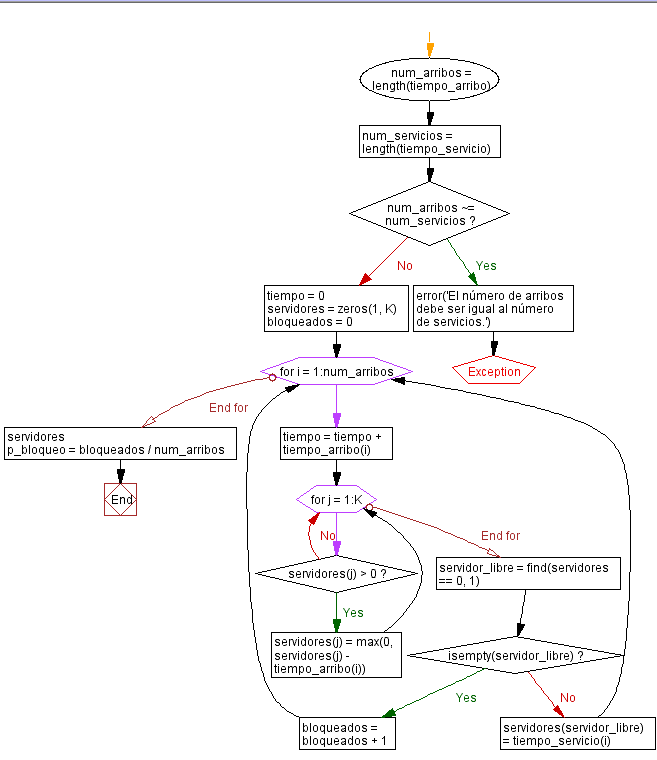

### Prueba con valores fijos

Para verificar el funcionamiento de la cola construida, se considerará la función `xxkk`, que toma como parámetros de entrada los vectores tea, tds y el valor k para el número de servidores:

tea = [1,2,3,7,2,3,8,0,5,7,2,3,1,8,7,2,3,7,2,3,7,2,3,7,2,3,4];
tds = [9,1,4,1,1,5,3,8,2,9,1,4,1,1,5,3,8,2,9,1,4,1,1,5,3,8,2];
k = 2;

y retorna todas las variables consideradas durante la simulación:

fprintf('La probabilidad de bloqueo es: %.5f\n', xxkk(tea,tds,k));

num_arribos = 27

num_servicios = 27

servidores =      4     2


La probabilidad de bloqueo es: 0.03704


tea = [1,2,3,7,2,3,8,0,5,7,2,3,1,8,7,2,3,7,2,3,7,2,3,7,2,3,4];
tds = [9,1,4,1,1,5,3,8,2,9,1,4,1,1,5,3,8,2,9,1,4,1,1,5,3,8,2];
k = 4;

y retorna todas las variables consideradas durante la simulación:

fprintf('La probabilidad de bloqueo es: %.5f\n', xxkk(tea,tds,k));

num_arribos = 27

num_servicios = 27

servidores =      4     2     0     0


La probabilidad de bloqueo es: 0.00000


### Prueba con valores enteros aleatorios

usuarios = 268;
tea = randi(270,1,usuarios)-1;
tds = randi(270,1,usuarios)-1;
k = 4;

fprintf('La probabilidad de bloqueo es: %.5f\n', xxkk(tea,tds,k));

num_arribos = 268

num_servicios = 268

servidores =    208     0     0     0


La probabilidad de bloqueo es: 0.00000


## Tercera Actividad

Realicen la simulación de la cola asignada variando $$A$=\frac{ $\lambda$}{$\mu$}$. Consideren que los elementos del vector de tiempos entre arribos consecutivos se distribuyen exponencialmente, con parámetro $ $\lambda$
$; y que los elementos del vector de tiempos de servicio se distribuyen exponencialmente, con parámetro $$\mu$
$. Como resultado principal, realicen la gráfica de la medida de bloqueo versus $$A$$. Verifiquen que los resultados de simulación coincidan con el valor teórico de la medida de bloqueo.

### Validación para un solo valor de A

lambda = 10;
mu = 12;
k = 2;
a=lambda/mu;
usuarios = 10000;
experimentos = 10000;
resultados = zeros(1,experimentos);

tic;
for n = 1:experimentos
    tea = exprnd(1/lambda,1,usuarios);
    tds = exprnd(1/mu,1,usuarios);
    resultados(n) = simular_cola_MMKK(tea,tds,k);
end
toc;

Elapsed time is 85.689645 seconds.


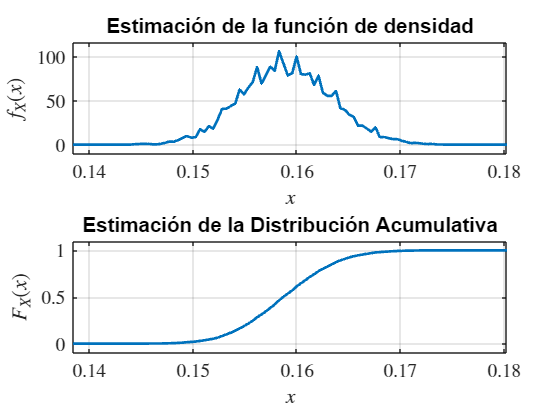

figure(1);
pdfcdfcontinua(resultados);

mean(resultados)

ans = 0.1592

Pk_Teorico =erlang_b(a,k)

Pk_Teorico = 0.1592

### Validación con $0<A<\infty$

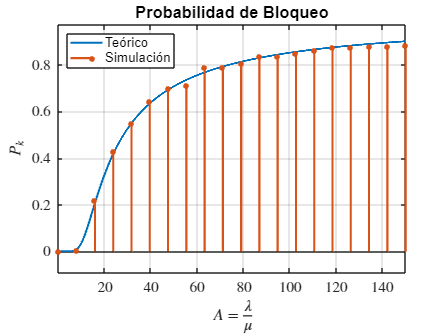

figure(5);
usuarios = 2000;
lambda = 8;
k = 15;

A = linspace(0.05,10*k,10000); % cambiar el 0.95 por el A sugerido en clase
teorico = zeros(1,numel(A));
for n = 1:numel(A)
    teorico(n) = erlang_b(A(n),k);
end
superplot(A,teorico);

hold on;

% Resultado de Simulación: promedios de bloqueo
A = linspace(0.05,10*k,20); % cambiar el 0.95 por el A sugerido en clase
mu = lambda./A;
promedios = zeros(1,numel(A));

for n = 1:numel(A)
    tea = exprnd(1/lambda,1,usuarios);
    tds =  exprnd(1/mu(n),1,usuarios);
    promedios(n) = simular_cola_MMKK(tea,tds,k); % usar su función 
    
end

superstem(A,promedios,'Probabilidad de Bloqueo',...
    '$A=\frac{\lambda}{\mu}$','${P_k}$');
xlim([0.05,10*k]);
hold off;

legend({'Teórico','Simulación'},'Location','northwest')

## Cuarta Actividad

Utilicen la función superfuncion, para generar cuatro funciones asociadas al conjunto de datos suministrados en clase. Muestren evidencias de la validez de sus funciones (comparación de las gráficas de las distribuciones de los datos y gráficas qqplot, por ejemplo).

### Distribución de la muestra BCpAug89.TL:

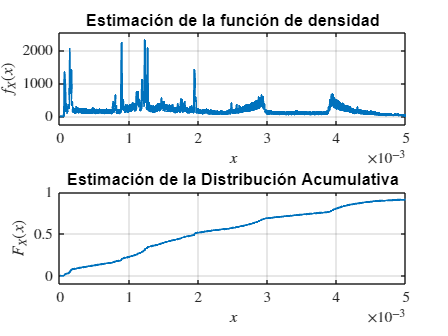

datos = load('BCpAug89.TL');
muestra = diff(datos(:,1)'); % Vector tea
figure(12);
pdfcdfcontinua(muestra,0,0.005);

### Codificación de la función para archivo BCpAug89.TL.

superfuncion(muestra,'agostornd_grupo3');

agostornd_grupo3.m codificado. Revisa tu carpeta de MATLAB, por favor.
Luego puedes ejecutar: agostornd_grupo3(m,n).


### Distribución de la función codificada agostornd_grupo3.

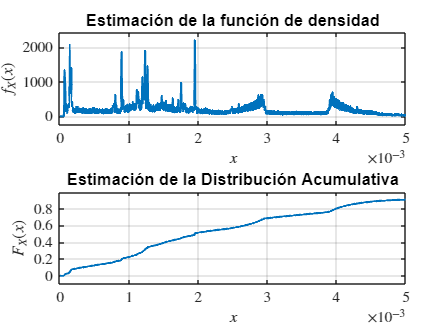

figure(13);
muestraagosto = agostornd_grupo3(1,1000000);
pdfcdfcontinua(muestraagosto,0,0.005);

### QQplot de la función codificada agostornd_grupo3.

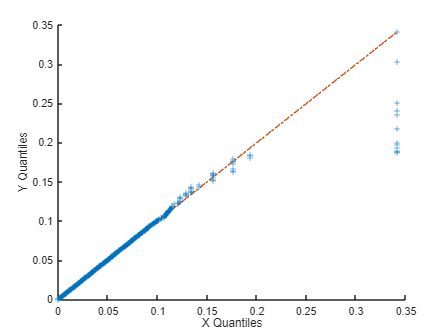

figure(14);
muestraagosto = agostornd_grupo3(1,1000000);
qqplot(muestraagosto,muestra);

Las desviaciones en las colas indican que los datos no siguen exactamente una distribución normal, pero esto no necesariamente significa que los datos no se aproximan en absoluto. Puede ser que los datos tengan algunas características de la normalidad con algunas diferencias en los extremos.

### Distribución de la muestra BCOct89Ext.TL:

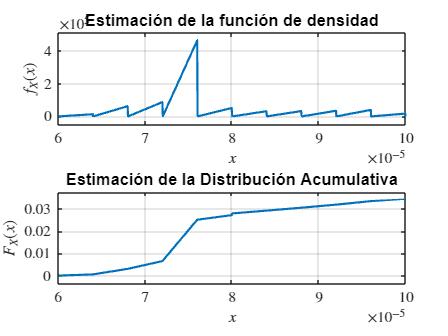

datos = load('BCOct89Ext.TL');
muestra = diff(datos(:,1)'); % Vector tea
figure(12);
pdfcdfcontinua(muestra,0.00006,0.0001);

### Codificación de la función para archivo BCOct89Ext.TL.

superfuncion(muestra,'octubrernd_grupo3');

octubrernd_grupo3.m codificado. Revisa tu carpeta de MATLAB, por favor.
Luego puedes ejecutar: octubrernd_grupo3(m,n).


### Distribución de la función codificada octubrernd_grupo3.

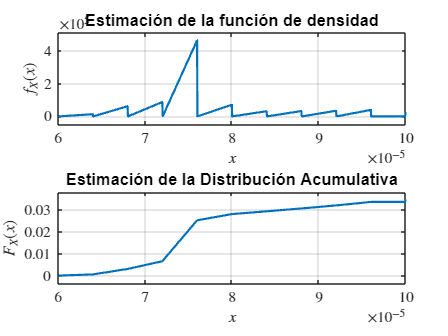

figure(16);
muestraoctubre = octubrernd_grupo3(1,1000000);
pdfcdfcontinua(muestraoctubre,0.00006,0.0001);

### QQplot de la función codificada octubrernd_grupo3.

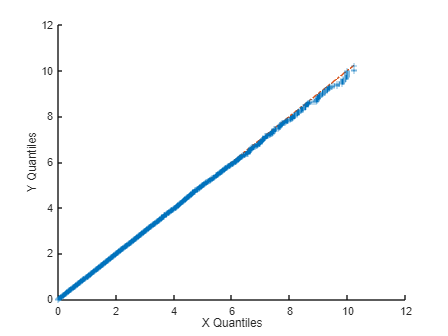

figure(17);
muestraoctubre = octubrernd_grupo3(1,1000000);
qqplot(muestraoctubre,muestra)

Dado que los puntos se alinean muy bien con la línea de referencia a lo largo de toda la gráfica, los datos parecen comportarse de manera muy similar a una distribución normal

### Distribución de la muestra BCpOct89.TL:

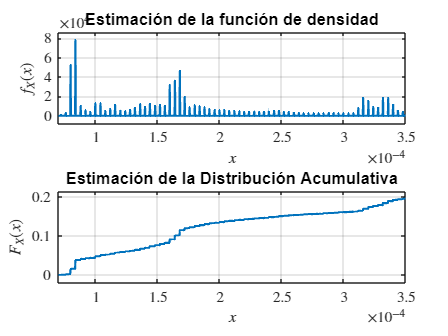

datos = load('BCpOct89.TL');
muestra = diff(datos(:,1)'); % Vector tea
figure(19);
%pdfcdfcontinua(muestra,0.00006,0.0001);
pdfcdfcontinua(muestra,0.00007,0.00035);

### Codificación de la función para archivo BCpOct89.TL.

superfuncion(muestra,'octubrebase_rnd_grupo3');

octubrebase_rnd_grupo3.m codificado. Revisa tu carpeta de MATLAB, por favor.
Luego puedes ejecutar: octubrebase_rnd_grupo3(m,n).


### Distribución de la función codificada octubrebase_rnd_grupo3.

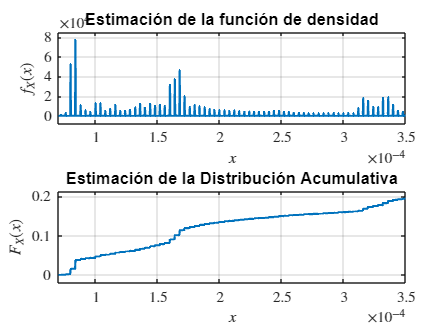

figure(20);
muestraoctubre_base = octubrebase_rnd_grupo3(1,1000000);
pdfcdfcontinua(muestraoctubre_base,0.00007,0.00035);

### QQplot de la función codificada octubrebase_rnd_grupo3.

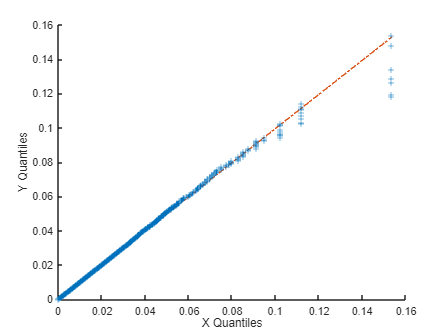

figure(17);
muestraoctubre_base = octubrebase_rnd_grupo3(1,1000000);
qqplot(muestraoctubre_base,muestra);

la muestra en la mayoría de los puntos se alinean con la línea de referencia en la parte central, sugiriendo que los datos se aproximan a una distribución normal en ese rango. Sin embargo, las desviaciones en las colas indican que los datos no siguen una distribución normal perfectamente en los extremo

### Distribución de la muestra BCOct89Ext4.TL:

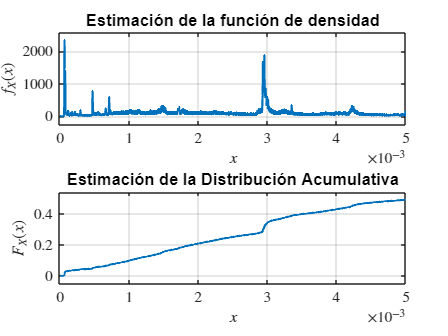

datos = load('BCOct89Ext4.TL');
muestra = diff(datos(:,1)'); % Vector tea
figure(21);
%pdfcdfcontinua(muestra,0.00006,0.0001);
pdfcdfcontinua(muestra,0,0.005);

### Codificación de la función para archivo BCOct89Ext4.TL.

superfuncion(muestra,'octubrebase_ext4_grupo3');

octubrebase_ext4_grupo3.m codificado. Revisa tu carpeta de MATLAB, por favor.
Luego puedes ejecutar: octubrebase_ext4_grupo3(m,n).


### Distribución de la función codificada octubrebase_ext4_grupo3.

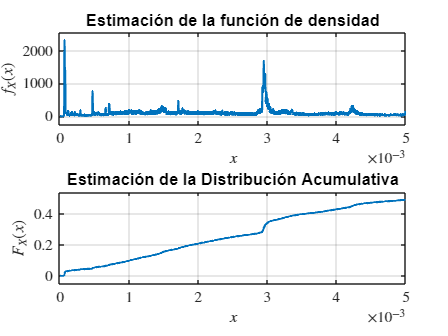

figure(22);
muestraoctubre_ext4 = octubrebase_ext4_grupo3(1,1000000);
pdfcdfcontinua(muestraoctubre_ext4,0,0.005);

### QQplot de la función codificada octubrebase_ext4_grupo3.

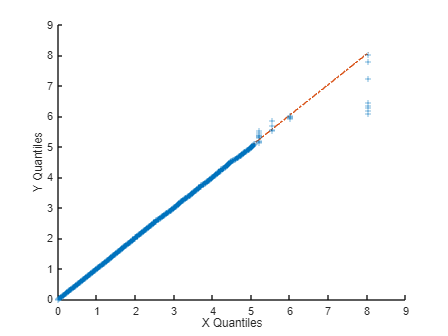

figure(23);
muestraoctubre_ext4 = octubrebase_ext4_grupo3(1,1000000);
qqplot(muestraoctubre_ext4,muestra);

la mayoría de los puntos se alinean con la línea de referencia en la parte central, sugiriendo que los datos se aproximan a una distribución normal en ese rango. Sin embargo, las desviaciones en las colas indican que los datos no siguen una distribución normal perfectamente en los extremo

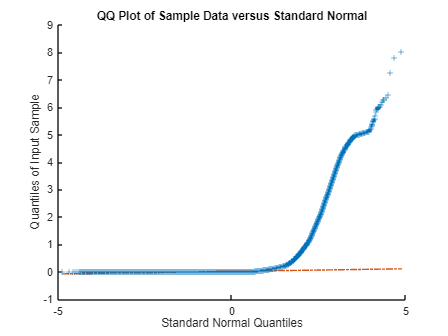

qqplot(muestra);

## Quinta Actividad

Realicen la simulación de la cola asignada variando $$A$=\frac{ $\lambda$}{$\mu$}$. Consideren que los elementos del vector de tiempos entre arribos consecutivos, se obtienen con cada una de las cuatro funciones de la cuarta actividad (para cada función consideren que el parámetro $$\lambda$$, se estima con el inverso multiplicativo de la media aritmética de los elementos del vector generado con cada una de las cuatro funciones: $\lambda \approx1/\bar{T_{arribo}}$ , y que los elementos del vector de tiempos de servicio se distribuyen exponencialmente, con parámetro $$\mu$$. Como resultado principal, realicen las cuatro gráficas de la probabilidad de bloqueo versus A. Comparen los resultados de simulación con el valor teórico (para distribuciones exponenciales) de la probabilidad de bloqueo.

### Distribución de la función codificada agostornd_grupo3.

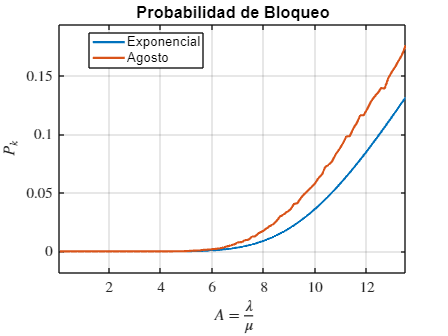

datos = agostornd_grupo3(1,1000000);
lambda = 1/mean(datos);
k=15;
Amin = 0.1;
Amax = 0.9*k;
simulaciones = 100;
A = linspace(Amin,Amax,simulaciones);
mu = lambda./A;
%usuarios = 1000000;
usuarios = 200000; %Cambiar usuarios
tiempomedio = zeros(1,numel(mu));
for n = 1:numel(mu)
    tea = agostornd_grupo3(1,usuarios);
    tds = exprnd(1/mu(n),1,usuarios);
    tiempomedio(n) = simular_cola_MMKK(tea,tds,k); % La función de la cola
end
A = linspace(Amin,Amax,1000);
mu = lambda./A;
teorico = zeros(1,numel(A)); 
for n = 1:numel(A)
    teorico(n) = erlang_b(A(n),k);% Valor teórico obtenido para la cola 
end
figure(24);
superplot(A,teorico,...
    'Probabilidad de Bloqueo','$A=\frac{\lambda}{\mu}$',...
    '${P_k}$');
hold on;

A = linspace(Amin,Amax,simulaciones);
superplot(A,tiempomedio);
hold off;

legend({'Exponencial','Agosto'},...
    'location','best');
xlim([Amin Amax]);

### Distribución de la función codificada octubrebase_rnd_grupo3.

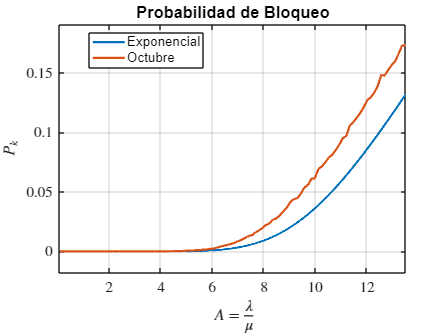

datos = octubrebase_rnd_grupo3(1,1000000);
lambda = 1/mean(datos);
k=15;
Amin = 0.1;
Amax = 0.9*k;
simulaciones = 100;
A = linspace(Amin,Amax,simulaciones);
mu = lambda./A;
%usuarios = 1000000;
usuarios = 200000; %Cambiar usuarios
tiempomedio = zeros(1,numel(mu));
for n = 1:numel(mu)
    tea = octubrebase_rnd_grupo3(1,usuarios);
    tds = exprnd(1/mu(n),1,usuarios);
    tiempomedio(n) = simular_cola_MMKK(tea,tds,k); % La función de la cola
end
A = linspace(Amin,Amax,1000);
mu = lambda./A;
teorico = zeros(1,numel(A)); 
for n = 1:numel(A)
    teorico(n) = erlang_b(A(n),k);% Valor teórico obtenido para la cola 
end
figure(25);
superplot(A,teorico,...
    'Probabilidad de Bloqueo','$A=\frac{\lambda}{\mu}$',...
    '${P_k}$');
hold on;

A = linspace(Amin,Amax,simulaciones);
superplot(A,tiempomedio);
hold off;

legend({'Exponencial','Octubre'},...
    'location','best');
xlim([Amin Amax]);

### Distribución de la función codificada octubrernd_grupo3.

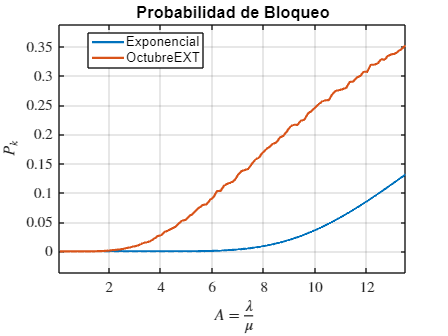

datos = octubrernd_grupo3(1,1000000);
lambda = 1/mean(datos);
k=15;
Amin = 0.1;
Amax = 0.9*k;
simulaciones = 100;
A = linspace(Amin,Amax,simulaciones);
mu = lambda./A;
%usuarios = 1000000;
usuarios = 200000; %Cambiar usuarios
tiempomedio = zeros(1,numel(mu));
for n = 1:numel(mu)
    tea = octubrernd_grupo3(1,usuarios);
    tds = exprnd(1/mu(n),1,usuarios);
    tiempomedio(n) = simular_cola_MMKK(tea,tds,k); % La función de la cola
end
A = linspace(Amin,Amax,1000);
mu = lambda./A;
teorico = zeros(1,numel(A)); 
for n = 1:numel(A)
    teorico(n) = erlang_b(A(n),k);% Valor teórico obtenido para la cola 
end
figure(26);
superplot(A,teorico,...
    'Probabilidad de Bloqueo','$A=\frac{\lambda}{\mu}$',...
    '${P_k}$');
hold on;

A = linspace(Amin,Amax,simulaciones);
superplot(A,tiempomedio);
hold off;

legend({'Exponencial','OctubreEXT'},...
    'location','best');
xlim([Amin Amax]);

### Distribución de la función codificada octubrernd_grupo3.

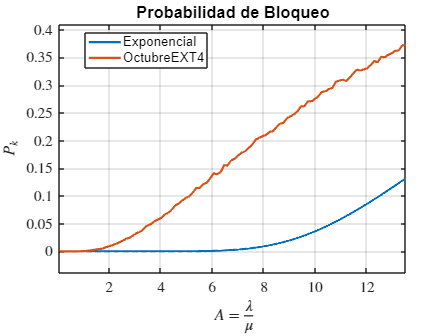

datos = octubrebase_ext4_grupo3(1,1000000);
lambda = 1/mean(datos);
k=15;
Amin = 0.1;
Amax = 0.9*k;
simulaciones = 100;
A = linspace(Amin,Amax,simulaciones);
mu = lambda./A;
%usuarios = 1000000;
usuarios = 200000; %Cambiar usuarios
tiempomedio = zeros(1,numel(mu));
for n = 1:numel(mu)
    tea = octubrebase_ext4_grupo3(1,usuarios);
    tds = exprnd(1/mu(n),1,usuarios);
    tiempomedio(n) = simular_cola_MMKK(tea,tds,k); % La función de la cola
end
A = linspace(Amin,Amax,1000);
mu = lambda./A;
teorico = zeros(1,numel(A)); 
for n = 1:numel(A)
    teorico(n) = erlang_b(A(n),k);% Valor teórico obtenido para la cola 
end
figure(26);
superplot(A,teorico,...
    'Probabilidad de Bloqueo','$A=\frac{\lambda}{\mu}$',...
    '${P_k}$');
hold on;

A = linspace(Amin,Amax,simulaciones);
superplot(A,tiempomedio);
hold off;

legend({'Exponencial','OctubreEXT4'},...
    'location','best');
xlim([Amin Amax]);

## Sexta Actividad

Identifiquen un escenario real de su disciplina, profesión, campo laboral, o investigación, en el que puedan aplicar el modelo de la cola asignada, y procedan a realizar una simulación de ejemplo. 

### Escenario de Aplicación: Gestión de Comunicaciones en Redes Inteligentes

En el contexto de sistemas de potencia eléctrica, un escenario importante para aplicaciónes del modelo Erlang B podría ser la gestión de comunicaciones en redes inteligentes o "smart grids", donde se requiere la transmitir  datos entre subestaciones eléctricas digitales y centros de control.

Descripción del escenario: En una red eléctrica inteligente, las subestaciones digitales y otros dispositivos de monitoreo envían datos de manera peridodica y eventos críticos a un centro de control que se presentan en subestaciones electricas. Estas comunicaciones pueden incluir información sobre el estado del sistema, mediciones de energía, alarmas y eventos de falla. La red de comunicaciones entre las subestaciones y el centro de control debe ser capaz de manejar estos datos en tiempo real, y cualquier retraso o pérdida de información puede afectar la operación segura y eficiente del sistema de potencia y  ademas afectar el suministro de energia para los diferentes usuarios.

Aplicación del modelo Erlang B:Podemos utilizar el modelo Erlang B para dimensionar la capacidad de la red de comunicaciones, determinando el número de canales de comunicación (o ancho de banda necesario) para minimizar la probabilidad de pérdida de datos debido a congestión en la red de comunicacion.

% Parámetros
llegada_media = 1 / 1; % Tiempo promedio entre llegadas (por ejemplo, cada 1 minuto)
servicio_media = 2; % Tiempo promedio de comunicación (por ejemplo, 2 minutos)

% Número de muestras
num_solicitudes = 1000;

% Generar tiempos de arribo y tiempos de servicio
% inter_arrival_times = exprnd(1 / llegada_media, num_solicitudes, 1);
tiempos_de_arribo = exprnd(1 / llegada_media, num_solicitudes, 1);
tiempos_de_servicio = exprnd(servicio_media, num_solicitudes, 1);

% Mostrar los primeros 10 valores de cada vector para verificar
% disp('Tiempos de Arribo (primeros 10):');
% disp(tiempos_de_arribo(1:10));

% disp('Tiempos de Servicio (primeros 10):');
% disp(tiempos_de_servicio(1:10));

% Valores del número de canales disponibles
canales_valores = [1, 2, 3, 4, 5]; % Ejemplos de diferentes capacidades de canales

% Resultados de la simulación
probabilidades_de_rechazo = zeros(size(canales_valores));

for i = 1:length(canales_valores)
    k = canales_valores(i); % Número de canales disponibles
    probabilidad_rechazo = xxkk(tiempos_de_arribo, tiempos_de_servicio, k);
    probabilidades_de_rechazo(i) = probabilidad_rechazo;
    fprintf('Número de Canales: %d, Probabilidad de Rechazo: %.4f\n', k, probabilidad_rechazo);
end

num_arribos = 1000

num_servicios = 1000

servidores = 3.0760

Número de Canales: 1, Probabilidad de Rechazo: 0.6530


num_arribos = 1000

num_servicios = 1000

servidores =     3.0760    0.1906


Número de Canales: 2, Probabilidad de Rechazo: 0.3750


num_arribos = 1000

num_servicios = 1000

servidores =     3.0760    0.1906         0


Número de Canales: 3, Probabilidad de Rechazo: 0.1930


num_arribos = 1000

num_servicios = 1000

servidores =     3.0760    0.1906         0    1.6583


Número de Canales: 4, Probabilidad de Rechazo: 0.0880


num_arribos = 1000

num_servicios = 1000

servidores =     3.0760    0.1906         0    1.6583         0


Número de Canales: 5, Probabilidad de Rechazo: 0.0330


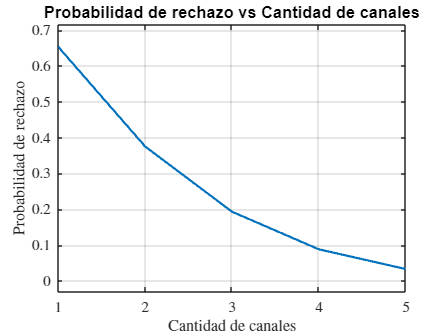

superplot(canales_valores,probabilidades_de_rechazo,'Probabilidad de rechazo vs Cantidad de canales', 'Cantidad de canales', 'Probabilidad de rechazo');

## Conclusiones

- A partir del método de la inversa se pueden generar datos aleatorios que permiten modelar distribuciones desconocidas, constituyendo una herramienta útil para simulaciones y análisis estadísticos.

- Este modelo matemático permite aproximar el comportamiento real de sistemas como telecomunicaciones, servicios de atención al cliente y cadenas de producción, facilitando la toma de decisiones sobre diversos parámetros para determinar el escenario más adecuado.

- El modelo es una herramienta para asegurar que los sistemas basados en colas sin espera puedan manejar eficientemente el tráfico, optimizando el uso de recursos y manteniendo la calidad del servicio.

- Ayuda a calcular la cantidad de operadores o sistemas necesarios para manejar las solicitudes sin rechazos durante picos de demanda, optimizando la capacidad de reserva del servicio.

- Los cuantiles ayudan a estimar y evaluar redes, asegurando que la capacidad sea suficiente para soportar la demanda en diversos momentos, reduciendo el riesgo de retrasos y la depreciación de la calidad del servicio.

- Gracias al análisis de colas como M/M/k/k, se pueden establecer acuerdos de nivel de servicio (SLA), asegurando que los recursos sean suficientes para manejar altos flujos de demanda sin un aumento excesivo en los tiempos de espera o atención.

## Referencias 

- Rocafiguera, E., & Barberán, P. (2019). *Análisis mediante teoría de colas*.

## Anexos

Repositorio de GitHub con todos los elementos usados en el trabajo. https://github.com/alejomora999/HM_2024_Trabajo_3